# LSB水印嵌入算法

## 1、加载原始图像和需要嵌入的信息

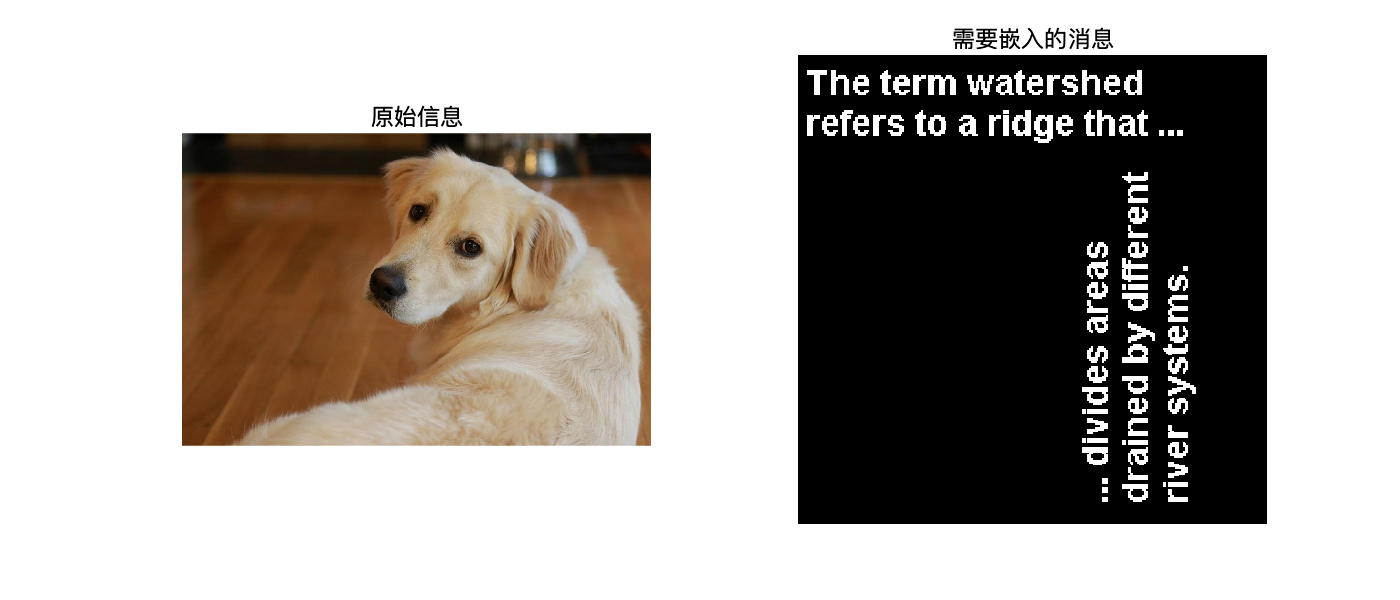

%读取载体图像
file_name= 'sherlock.jpg';
orig_image=imread(file_name);
%读取秘密信息'text.png'
file_name=;
message=imread(file_name);
% message=double(message);
% message=fix(message./2);
% message=uint8(message);
figure('Position',[0,0,700,300])
subplot(1,2,1);
imshow(orig_image);
title('原始信息');
subplot(1,2,2);
imshow(message);
title('需要嵌入的消息');

## 2、水印嵌入算法

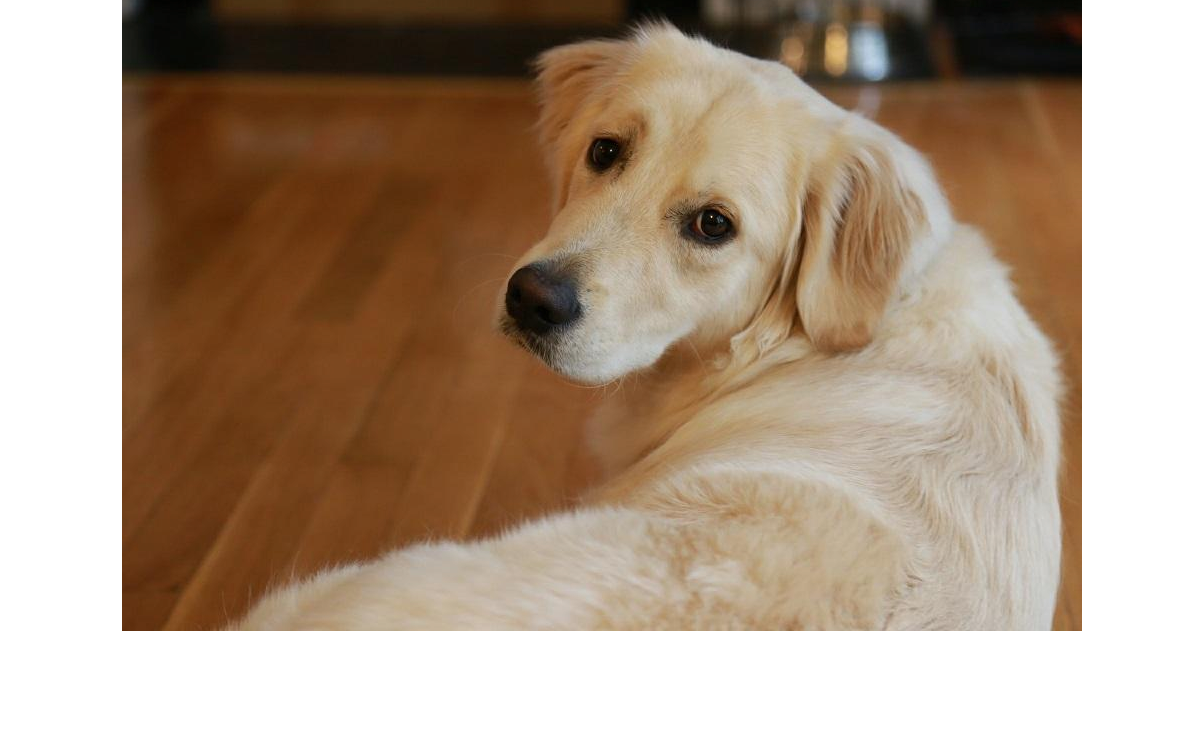

%确定载体图像大小
Hc=size(orig_image,1);
Nc=size(orig_image,2);
%确定秘密信息大小
Hm=size(message,1);
Wm=size(message,2);

%确定秘密信息生成载体图像大小的水印信息
watermark=zeros(Hc,Nc);
for i=1:Hc
    for j=1:Nc
        watermark(i,j)=message(mod(i,Hm)+1,mod(j,Wm)+1);
    end
end

%将水印信息嵌入载体图像
watermarked_image=orig_image;
for i=1:Hc
    for j=1:Nc
        watermarked_image(i,j,1)=bitset(watermarked_image(i,j,1),1,watermark(i,j));
    end
end

figure();
imshow(watermarked_image);
title('带有数字水印的图片');

## 3、提取水印算法

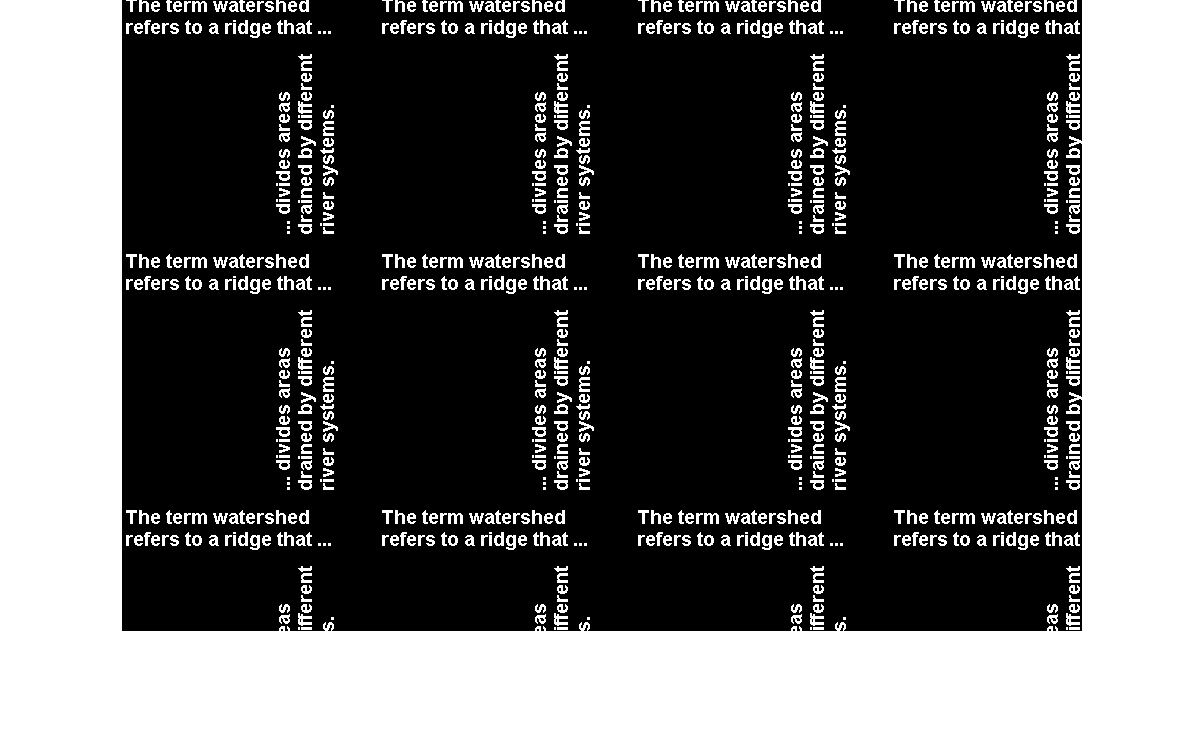

% 水印图像的大小
[Hw,Ww,~]=size(watermarked_image);
% 水印信息提取过程
watermark2=zeros(Hw,Ww);
for i=1:Hw
    for j=1:Ww
        watermark2(i,j)=bitget(watermarked_image(i,j,1),1);
    end
end
watermark2=2*double(watermark2);
%显示水印
figure();
imshow(watermark2);
title('恢复出来的水印');

注：

- MATLAB 自带图片一般位于路径/Applications/MATLAB_R2021a.app/toolbox/images/imdata/